07222113邓俊烽第六章

%主程序
clear;clc;
%测试上机习题6
%第一问见SolPolMax.m
%第二问
a1 = [3,-5,1];
disp(['equ1: ',num2str(a1)]);

equ1: 3 -5  1


a = a1;
x = SolPolMax(a);

迭代次数为31
迭代时间为0.0005217s


f = 0;
for i=0:length(a1)-1
    f = f + x^i*a(i+1);
end
f = f + x^length(a);
xtext = EigSolPolMax(a);
disp(['x1 = ',num2str(x),'   调用Matlab内置的eig求得的最大特征值为xtext1=', num2str(xtext),', f1 = ',num2str(f)]);

x1 = -3   调用Matlab内置的eig求得的最大特征值为xtext1=-3, f1 = -1.6783e-11



a2 = [1,-3,0];
disp(['equ2: ',num2str(a2)]);

equ2: 1 -3  0


a = a2;
x = SolPolMax(a);

迭代次数为146
迭代时间为0.0002497s


f = 0;
for i=0:length(a1)-1
    f = f + x^i*a(i+1);
end
f = f + x^length(a);
xtext = EigSolPolMax(a);
disp(['x2 = ',num2str(x),'  调用Matlab内置的eig求得的最大特征值为xtext2=', num2str(xtext),', f2 = ',num2str(f)]);

x2 = -1.8794  调用Matlab内置的eig求得的最大特征值为xtext2=-1.8794, f2 = 9.9387e-12



a3 = [-1000,790,-99902,79108.9,9802.08,10891.01,208.01,101];
disp(['equ3: ',num2str(a3)]);

equ3: -1000             790          -99902         79108.9         9802.08        10891.01          208.01             101


a = a3;
x = SolPolMax(a);

迭代次数为13
迭代时间为0.0001011s


textx=EigSolPolMax(a);
f = 0;
for i=0:length(a1)-1
    f = f + x^i*a(i+1);
end
f = f + x^length(a);
xtext = EigSolPolMax(a);
disp(['x3 = ',num2str(x),'  调用Matlab内置的eig求得的最大特征值为xtext3=', num2str(xtext),', f3 = ',num2str(f)]);

x3 = -100  调用Matlab内置的eig求得的最大特征值为xtext3=-100, f3 = 9999999000986812


clear;clc;
%第一问见FindEig
%第二问
disp('---------');

---------


a = zeros(1,41);
a([1,4]) = 1;
n = length(a);
A = diag(ones(1,n-1),-1);
A(:,end) = -a';%构造A的系数矩阵
disp('x^41+x^3+1=0的解 :')

x^41+x^3+1=0的解 :


[~,~,Eig]=ImpQR(A)

times : 88


Eig =      -9.524838752140808e-01 + 0.000000000000000e+00i
      5.075686394679133e-01 - 8.105734388527183e-01i
      5.075686394679133e-01 + 8.105734388527183e-01i
      4.171515782555862e-01 - 8.710673095162530e-01i
      4.171515782555862e-01 + 8.710673095162530e-01i
     -9.681403415182825e-01 - 1.208669554211482e-01i
     -9.681403415182825e-01 + 1.208669554211482e-01i
      6.323398270643705e-01 - 7.534011999238163e-01i
      6.323398270643705e-01 + 7.534011999238163e-01i
      2.898121310678400e-01 - 9.464236746687591e-01i


disp(Eig);

     -9.524838752140808e-01 + 0.000000000000000e+00i
      5.075686394679133e-01 - 8.105734388527183e-01i
      5.075686394679133e-01 + 8.105734388527183e-01i
      4.171515782555862e-01 - 8.710673095162530e-01i
      4.171515782555862e-01 + 8.710673095162530e-01i
     -9.681403415182825e-01 - 1.208669554211482e-01i
     -9.681403415182825e-01 + 1.208669554211482e-01i
      6.323398270643705e-01 - 7.534011999238163e-01i
      6.323398270643705e-01 + 7.534011999238163e-01i
      2.898121310678400e-01 - 9.464236746687591e-01i
      2.898121310678400e-01 + 9.464236746687591e-01i
     -9.563390113283351e-01 - 2.737762090870263e-01i
     -9.563390113283351e-01 + 2.737762090870263e-01i
      7.537195304431219e-01 - 6.553802760027372e-01i
      7.537195304431219e-01 + 6.553802760027372e-01i
      1.391654349763842e-01 - 9.924767337008796e-01i
      1.391654349763842e-01 + 9.924767337008796e-01i
     -9.105111349337174e-01 - 4.255281513157950e-01i
     -9.105111349337174e-01 + 4.25528151315795

disp('测试f')

测试f


for i = 1:length(Eig)
    f(i) = Eig(i)^41+Eig(i)^3 + 1;
end
disp(f');

      4.662936703425657e-15 + 0.000000000000000e+00i
      5.329070518200751e-15 + 9.117706589734098e-15i
      5.329070518200751e-15 - 9.117706589734098e-15i
      2.442490654175344e-15 - 1.829092433069945e-14i
      2.442490654175344e-15 + 1.829092433069945e-14i
     -7.327471962526033e-15 - 2.275957200481571e-15i
     -7.327471962526033e-15 + 2.275957200481571e-15i
      4.884981308350689e-15 + 5.662137425588298e-15i
      4.884981308350689e-15 - 5.662137425588298e-15i
      5.107025913275720e-15 - 1.043609643147647e-14i
      5.107025913275720e-15 + 1.043609643147647e-14i
     -7.549516567451064e-15 - 2.109423746787797e-15i
     -7.549516567451064e-15 + 2.109423746787797e-15i
     -3.663735981263017e-14 - 6.739053759474700e-14i
     -3.663735981263017e-14 + 6.739053759474700e-14i
      3.108624468950438e-15 + 7.771561172376096e-15i
      3.108624468950438e-15 - 7.771561172376096e-15i
     -1.887379141862766e-14 - 2.386979502944087e-14i
     -1.887379141862766e-14 + 2.38697950294408

disp('---------');

---------


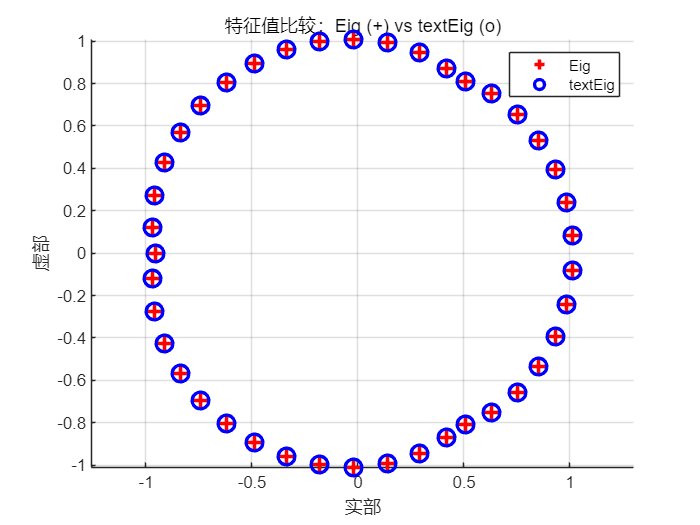

textEig=sort(eig(A));
% 绘制实部和虚部
figure;
hold on;
% 绘制 Eig，用 + 表示
scatter(real(Eig), imag(Eig), 100, 'r+', 'LineWidth', 2); % 红色 + 表示 Eig
% 绘制 textEig，用 o 表示
scatter(real(textEig), imag(textEig), 100, 'bo', 'LineWidth', 2); % 蓝色 o 表示 textEig
% 图形设置
xlabel('实部');
ylabel('虚部');
title('特征值比较：Eig (+) vs textEig (o)');
legend('Eig', 'textEig');
grid on;
axis equal; % 保持横纵轴比例一致
hold off;


%第三问
A = [9.1 3.0 2.6 4.0;
    4.2 5.3 4.7 1.6;
    3.2 1.7 9.4 0;
    6.1 4.9 3.5 6.2];
x = [0.9,1.0,1.1];
for i = 1:length(x)
    A(3,4) = x(i);
    disp(['x = ',num2str(x(i))]);
    disp('eig:');
    [~,~,Eig]=ImpQR(A);
    disp(Eig);
end

x = 0.9


eig:


times : 8


      2.870401735770235e+00 - 6.428911294724607e-01i
      2.870401735770235e+00 + 6.428911294724607e-01i
      6.819518337520939e+00 + 0.000000000000000e+00i
      1.743967819093857e+01 + 0.000000000000000e+00i



x = 1


eig:


times : 7


      2.867999246456047e+00 - 6.887473552591606e-01i
      2.867999246456047e+00 + 6.887473552591606e-01i
      6.787516591558544e+00 + 0.000000000000000e+00i
      1.747648491552938e+01 + 0.000000000000000e+00i



x = 1.1


eig:


times : 7


      2.865457870674265e+00 - 7.321697391152503e-01i
      2.865457870674265e+00 + 7.321697391152503e-01i
      6.756056187177516e+00 + 0.000000000000000e+00i
      1.751302807147395e+01 + 0.000000000000000e+00i



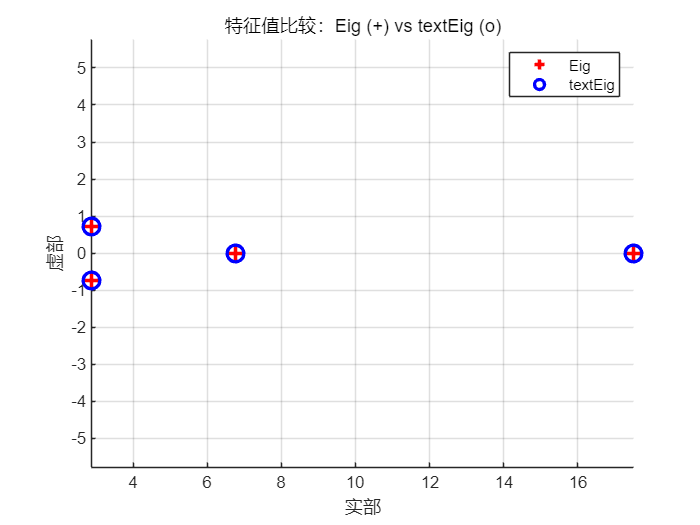

textEig=sort(eig(A));
% 绘制实部和虚部
figure;
hold on;
% 绘制 Eig，用 + 表示
scatter(real(Eig), imag(Eig), 100, 'r+', 'LineWidth', 2); % 红色 + 表示 Eig
% 绘制 textEig，用 o 表示
scatter(real(textEig), imag(textEig), 100, 'bo', 'LineWidth', 2); % 蓝色 o 表示 textEig
% 图形设置
xlabel('实部');
ylabel('虚部');
title('特征值比较：Eig (+) vs textEig (o)');
legend('Eig', 'textEig');
grid on;
axis equal; % 保持横纵轴比例一致
hold off;